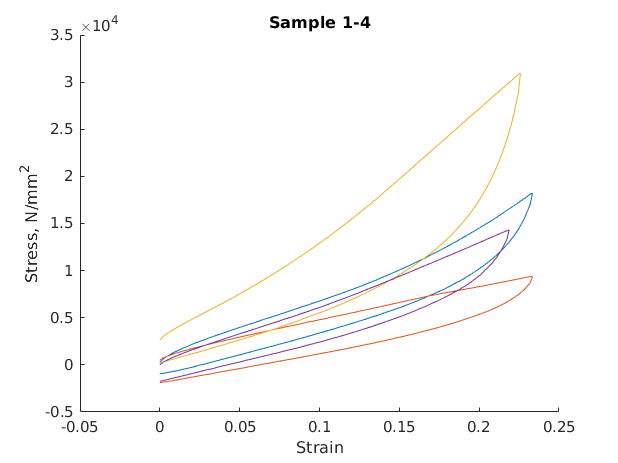

%% Load parameters

allParameters = readmatrix(uigetfile('*.xlsx'));
%%
[filename, filepath] = uigetfile('*.csv');
figure; hold on;
for i = 1:4
    [stress, strain, plotTitle] = process(allParameters,i, filename, filepath);
    makePlot(strain, stress, 'Sample 1-4' );
end
hold off

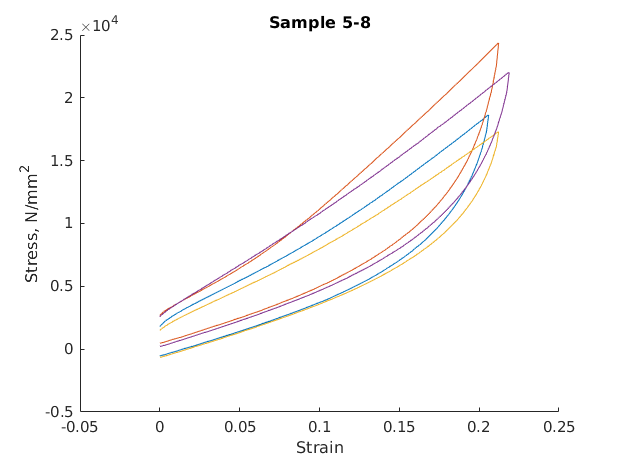

figure; hold on;
for i = 5:8
    [stress, strain, plotTitle] = process(allParameters,i, filename, filepath);
    makePlot(strain, stress, 'Sample 5-8');
end
hold off

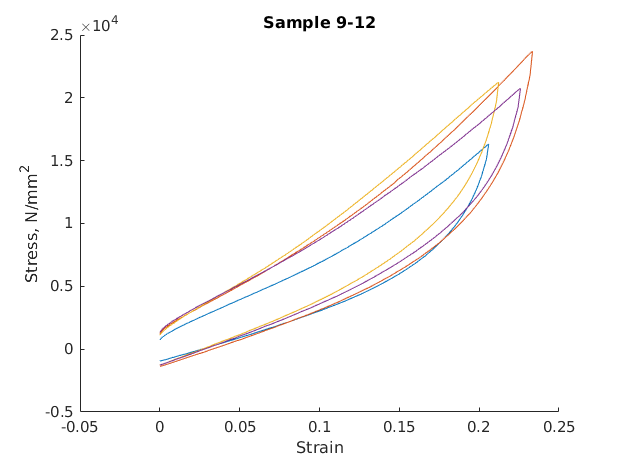

figure; hold on;
for i = 9:12
    [stress, strain, plotTitle] = process(allParameters,i, filename, filepath);
    makePlot(strain, stress, 'Sample 9-12');
end
hold off

%%

function [stress, strain, plotTitle] = process(allParameters, i, filename, filepath)
    for j=1:1
        %Match pattern to dynamically read the files
        filename = regexprep(filename, '_\d+\d?+_+\d', ['_',num2str(i),'_',num2str(j)]);
        T = readmatrix([filepath filename]);
        %time = T(:,1);
        displacement = T(:,2).*1e-3; %convert to m
        force=T(:,3);
        plotTitle=['Sample ' num2str(i)];
        
        %% Process Data
        % set parameters for the particular graph we're working on.
        parameters=allParameters(allParameters(:,3)==i,:);
        %Take dimensions from our set of parameters
        A=parameters(6)*parameters(8)*1e-6;
        L = parameters(8)*1e-3;
        stress=force/A;
        strain=displacement/L;
    end
end

function makePlot(x, y, makeTitle)
    plot(x,y)
    xlabel('Strain'); ylabel('Stress, N/mm^2')
    title(makeTitle);
end